# 2. iDMRG (infinite-size Density Matrix Renormalization Group)

Author: 조성주,  최윤식

## Problem

In this project, we are going to implement the infinite-size DMRG (iDMRG) for the anti-ferromagnetic S = 1/2 Heisenberg chain with open boundary conditions,


$$\hat{H}_\text{Heisenberg} = \sum_{\langle ij\rangle} \left[ \hat{{S}}_i^z  \hat{S}_j^z + \frac{1}{2} (\hat{S}_i^+ \hat{S}_j^-+\hat{S}_i^- \hat{S}_j^+) \right],$$


and the Ising model in a transverse field with open boundary conditions,


$$\hat{H}_\text{Ising} = \sum_{\langle ij\rangle}  \hat{{S}}_i^z  \hat{S}_j^z + \lambda\sum_i \hat S_i^x ,$$
				

where $\hat{\;S_i }$ are local spin-1/2 operators on site i. Here we refer to the figures and equations of Ref. 1. 

References			

[1] I. P. McCulloch, [arXiv:0804.2509 (2008)](https://arxiv.org/abs/0804.2509).

[2] S. R. White, [Phys. Rev. Lett. 69, 2863 (1992)](https://journals.aps.org/prl/abstract/10.1103/PhysRevLett.69.2863). 

clear

% iDMRG parameters
Nkeep = 30;
Nmax = 2e3;

% model definition
lamb = 1;

% Local operators
[S,I] = getLocalSpace('Spin',1/2);
H_H = contract(S,3,3,permute(conj(S),[2 1 3]),3,3); % Heisenberg
H_I = contract(S(:,:,2),3,3,conj(S(:,:,2)),3,3); % Ising
H_I = H_I + lamb * sqrt(2)*(contract(S(:,:,1),3,3,1,3,3)+contract(S(:,:,3),3,3,1,3,3)); % transverse field



## Point of Interest

- compare with Vidal's iTEBD : faster convergence because power method is not an efficient eigensolver. And Trotter decomposition requires careful scaling of time-step to zero for convergence.

- advantage of using MPS

- advantage of using MPO

## a)

Implement the iDMRG for translation invariant systems of a two-site unit cell. The procedure is summarized in Fig. 1. 		

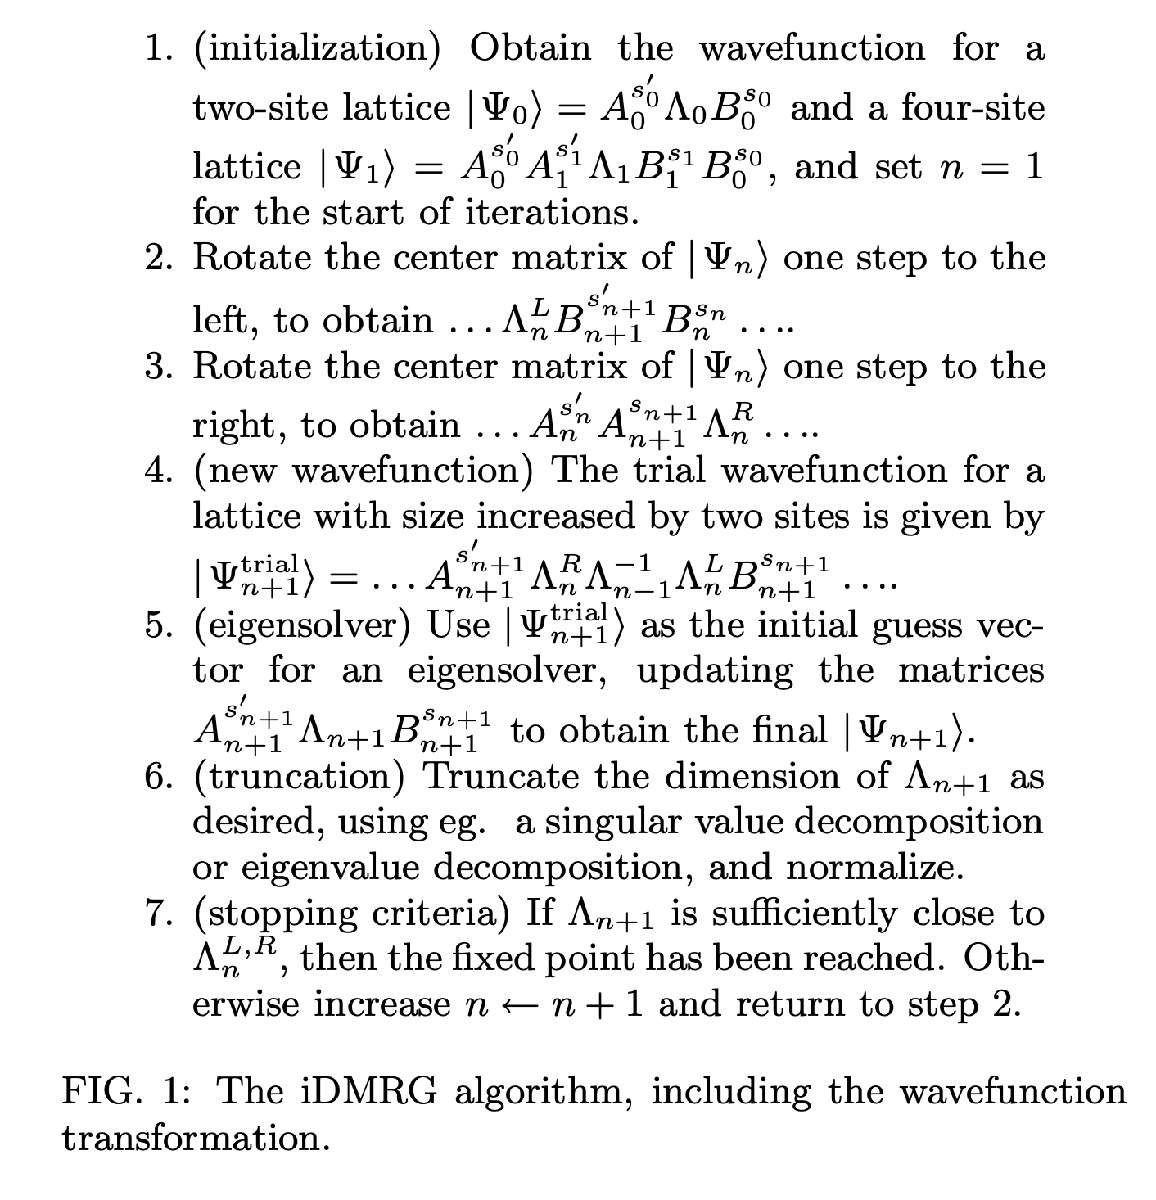		

% 1. initialize wavefunction
% Initialize with random Lambda and Gamma
Lambda = cell(1,2);
Gamma = cell(1,2);
for itn = (1:numel(Lambda))
    Lambda{itn} = rand(Nkeep,1);
    Gamma{itn} = rand(Nkeep,Nkeep,size(I,2));
end

% 2~7 loop : in function iDMRG_GS.m
[Lambda,Gamma,Eiter] = iDMRG_GS(Lambda,Gamma,H_H,Nkeep,Nmax); % Heisenberg
[Lambda,Gamma,Eiter] = iDMRG_GS(Lambda,Gamma,H_I,Nkeep,Nmax); % Ising


## b)

Benchmark your implementation by computing the ground state energy per site for the Heisenberg model and compare with the exact result for an infinite chain $e_0 = (1/4)-\ln(2)$ [2]. The energy per site $e_0$can be extracted from the difference between total energies $E_0
$ for two consecutive iDMRG iteration, $e_0 \left(N\right)=\frac{\left\lbrack E_0 \left(N\right)-E_0 \left(N-2\right)\right\rbrack }{2}$ . Check your results with different bond dimensions D = 20, 30, 40, 50. (With D = 20 or 50, you would be able to achieve decent accuracy in energy $\approx {10}^{-4}$ or ${10}^{-5}$,respectively.)

## c)

Verify the claim in Ref. 1 that the trial wave function used in the step 4 of Fig. 1 is a good choice, by computing the fidelity $1-\langle \;\Psi {\;}_n^{\textrm{trial}} |\Psi {\;}_n \rangle \;$. Make a plot similar to Fig. 2 for the Heisenberg model. 						

	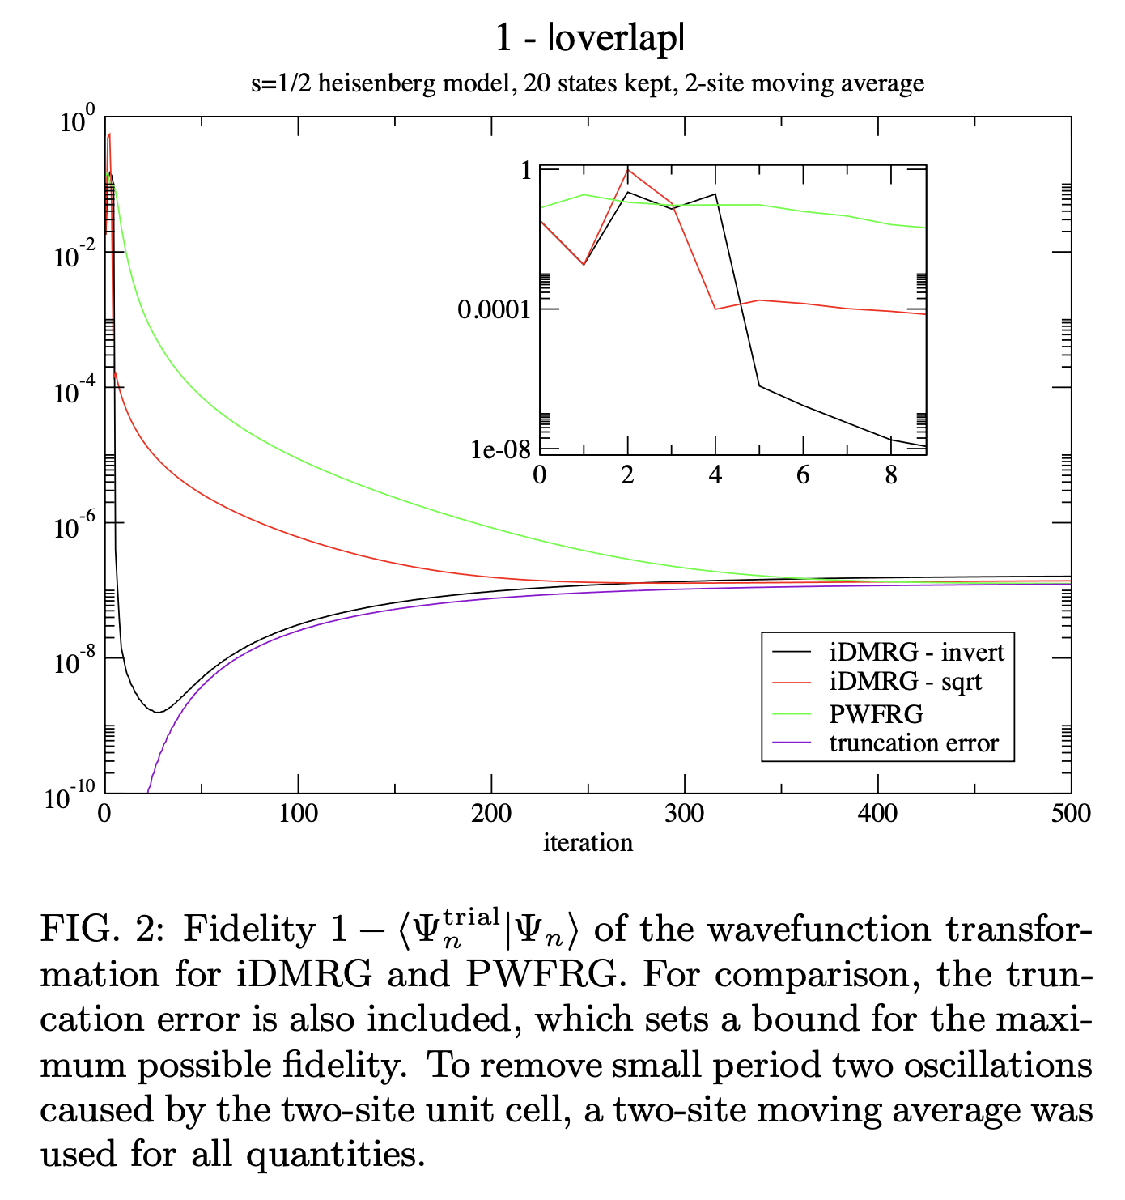

## d)

Analyze the behavior of iDMRG for the Ising model at the critical point $\lambda$=1/2 by studying the spectrum of the transfer operator [see Eq. (28)]. Make a plot similar to Fig. 4. 							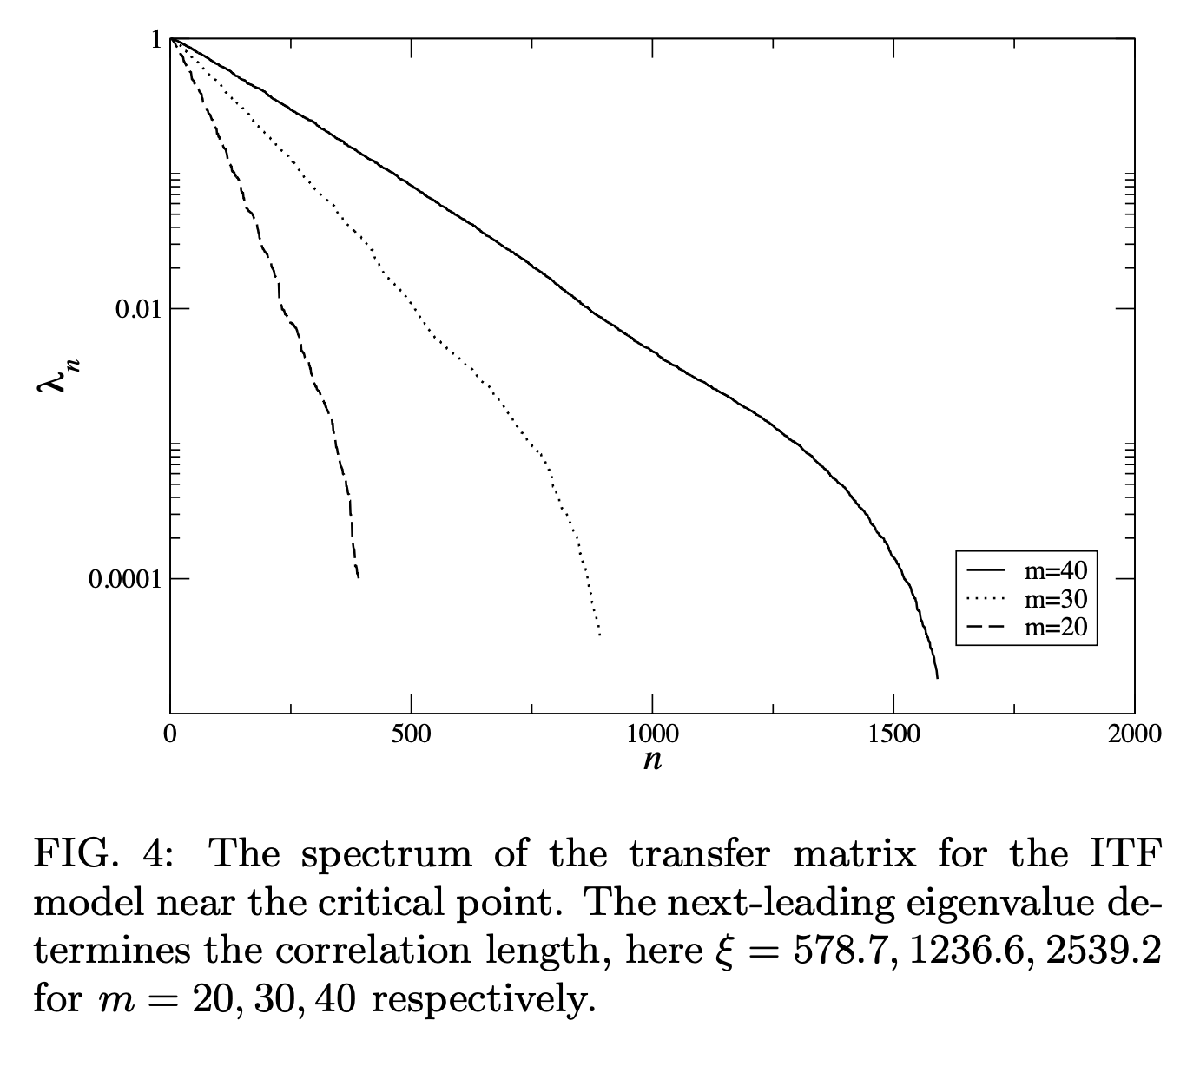		

## comparing with iTEBD